# **Test harness for rk4          **

A short test harness script to explore the implementation of an ODE solver.  We'll specifically look at:

- implementing our own fixed step solver (... because we're studying "Numerical Methods")

- using the MATLAB ode45 solver

`Bradley Horton : 01-Mar-2016, bradley.horton@mathworks.com.au`

**The analytical solution for a spring mass damper system:**

The test system that we'll consider is a familiar one:


$$m\thinspace\ddot{x}(t) + c \thinspace.\thinspace\dot{x}(t) + k \thinspace.\thinspace x(t) = F$$


Let's solve the analytical solution of this using the ***Symbolic toolbox*** for MATLAB.

sympref('HeavisideAtOrigin','default');

Define the Mechanical system parameters:

m = 1      % (kg)

m = 1

c = 2*0.2*3 % (N/(m/sec))

c = 1.2000

k = 9       % (N/m)

k = 9

Define the system INITIAL conditions

% define some INITIAL conditions
init_x    = 1;
init_xdot = 0;

Find the analytical solution to the 2nd order ODE.  Explore an excitation case involing a STEP type function

Recall the ODE that we need to solve:  $m\thinspace\ddot{x}(t) + c \thinspace.\thinspace\dot{x}(t) + k \thinspace.\thinspace x(t) = F$

clear x f t v

% define some SYMBOLIC variables
syms t f x(t)

% here is our STEP function
% we're applying a 15 seconds delay and the STEP magnitude is 3 
f  = 3*heaviside(t-15);

% construct the SYMBOLIC 2nd order ODE 
dx = diff(x);
EQ = m*diff(x,2) + c*diff(x,1) + k*x == f;

% now find the analytical solution applying our IC's
x = dsolve( EQ,   x(0)==init_x,    ...
                 dx(0)==init_xdot, ...
                 'IgnoreAnalyticConstraints',false);
simplify(x)

$$ans = \begin{array}{l} \frac{\mathrm{heaviside}\left(t-15\right)}{3}+\sigma_{1}\,\cos\left(\sigma_{2}\right)+\frac{\sqrt{6}\,\sigma_{1}\,\sin\left(\sigma_{2}\right)}{12}-\frac{\mathrm{heaviside}\left(t-15\right)\,\sigma_{1}\,{\mathrm{e}}^{9}\,\cos\left(\sigma_{2}-18\,\sqrt{6}\right)}{3}-\frac{\sqrt{6}\,\mathrm{heaviside}\left(t-15\right)\,\sigma_{1}\,{\mathrm{e}}^{9}\,\sin\left(\sigma_{2}-18\,\sqrt{6}\right)}{36}\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-\frac{3\,t}{5}}\\ \sigma_{2}=\frac{6\,\sqrt{6}\,t}{5} \end{array}$$

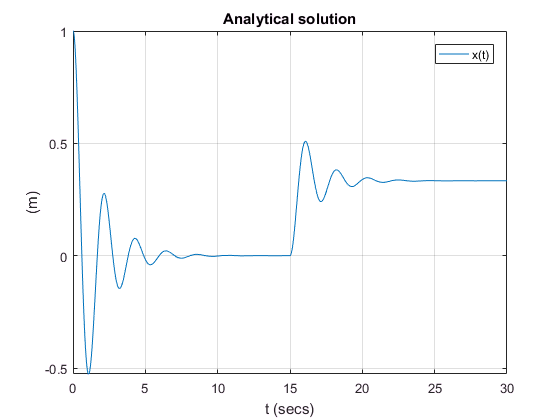


% and plot x 
figure;
   fplot(x, [-0.01, 30]);
   xlabel('t (secs)'); ylabel('(m)'); grid('on'); legend('x(t)');
   title('Analytical solution');

% save the analytical solution
x_anal_fh = matlabFunction(x);

# Numerical solution:

So far we've looked at finding an analytical solution to the mechanical 1-dof system. An alternate approach is to solve the problem numerically. This numerical approach requires that we convert our original problem into a new problem involving only 1st order ODEs.  Let's look at how we do this.  

We consider the general *n-dof* case:  $M \ddot{X} + C\dot{X} + KX = F$  where $X \in R^{n\times1}$ and then we repackage it into this form:

                 $\pmatrix{
\ddot{X} \cr
\dot{X} \cr
}$ = $\pmatrix{
-M^{-1}C & -M^{-1}K \cr
I_{n \times n} & 0_{n \times n} \cr
}$$\times \pmatrix{
\dot{X} \cr
X \cr
}$  +  $\pmatrix{
M^{-1}{F} \cr
0_{n \times 1} \cr
}$

which we can abbreviate to:

 $\dot{Z} = A \times Z + G$     where:     $Z =  \pmatrix{
\dot{X} \cr
X \cr
} \in R^{2n \times 1}$   

and   $G = \pmatrix{
M^{-1}{F} \cr
0_{n \times 1} \cr
}$

From here, we can either:

-  write our own ODE solver (eg: perhaps we're a student in our 2nd year "numerical methods" class

- OR, we can use one of MATLAB's ODE solvers, such as `ode45()`.

Let's look at both options.

# **OPTION_1:**  Writing our own 4th order Runge Kutta algorithm:

The file `bh_ode4.m` contains an implementation of the classic 4th order Runge Kutta algorithm.  Here is what it looks like:

dbtype('bh_ode4.m')


1     function [t_col, y_mat] = bh_ode4(f,tspan,y0,options,h)
2     
3         t_end      = tspan(2);
4         N_steps    = round(t_end/h);
5         N          = 1 + N_steps;
6         
7         t_col      = h * [0:(N-1)]'       ;
8         y_mat      = zeros(N, length(y0) );
9     
10        y_mat(1,:) = [y0(:)]' ;
11        t_col(1)   = 0;
12        
13        for kk=1:N_steps
14            t_kk           =  t_col(kk);
15            y_kk           =  y_mat(kk,:)';
16            y_next         =  LOC_rk4(f, t_kk, y_kk, h);
17            
18            y_mat(kk+1, :) = y_next';
19        end
20    
21    end % MAIN function
22    
23    function y_next = LOC_rk4(f,t,y,h)
24        k1 = h * f(t,y);
25        k2 = h * f(t + h/2, y+ k1/2 );
26        k3 = h * f(t + h/2, y+ k2/2 );
27        k4 = h * f(t + h  , y+ k3   );
28    
29        y_next = y +  k1/6  +  k2/3  +  k3/3  +  k4/6;
30    end
31    


So let's use this to solve the same mechanical system that we previously determined the analytic solution for.

% start with a clean slate
clear x f t v

% define our excitation function
F = @(t) (3*double(t>15));

% Define your INITIAL conditions
z_init = [ init_xdot ;
           init_x    ;  ];

% define the 1st order system to solve
MY_SYSTEM = @(t, z) ( [-c/m, -k/m; ...
                          1,    0]*z(:)  + [F(t)/m;0] );

% Define some ODE solver settings
t_span     = [0 30];

% fixed step used by solver
dt = 0.001;

% OK: let's use our ODE solver
[rk4_T,rk4_Z]  = bh_ode4(MY_SYSTEM, t_span, z_init, [], dt);

**Let's plot the Numeric solution AND the analytical solution:**

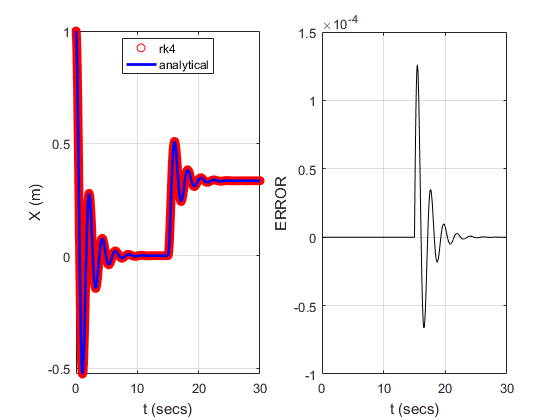

rk4_X     = rk4_Z(:,2);  
anal_x    = x_anal_fh( rk4_T );
err       = (anal_x - rk4_X);

figure;
subplot(1,2,1);
   plot(rk4_T,  rk4_X, 'or');    hold on
   plot(rk4_T, anal_x, '-b', 'LineWidth',2);
      xlabel('t (secs)'); ylabel('X (m)'); grid('on'); axis('tight');
      legend({'rk4','analytical'}, 'Location', 'best'); 

subplot(1,2,2);
   plot(rk4_T,  err, '-k');  
   xlabel('t (secs)'); ylabel('ERROR'); grid('on');

# **OPTION_2:**  use MATLAB's `ode45` solver:

MATLAB has several ODE solvers, one of them is called `ode45`.  Let's have a look at how to call it, using the same problem that we looked at in the previous section. 

% define some options for the adaptive step solver
my_options = odeset('RelTol', 1e-7, 'AbsTol', 1e-7);

% use ODE45 to numerically solve your system
%[T,Y] = solver(odefun,   tspan,  z0,     options)
[T,Z]  = ode45(MY_SYSTEM, t_span, z_init, my_options);


## **Let's plot the Numeric solution AND the analytical solution:**

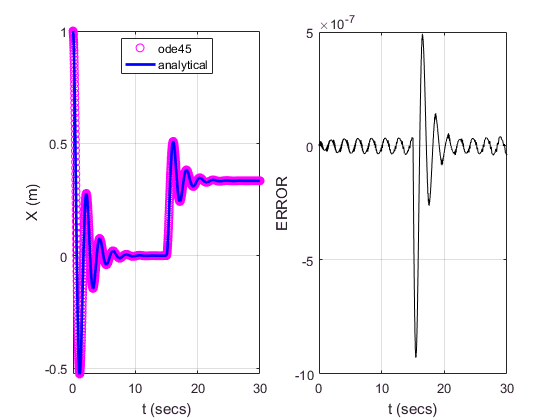

X         = Z(:,2);
anal_x    = x_anal_fh( T );
err       = (anal_x - X);

figure;
subplot(1,2,1);
   plot(T,      X, 'om');    hold on
   plot(T, anal_x, '-b', 'LineWidth',2);
      xlabel('t (secs)'); ylabel('X (m)'); grid('on'); axis('tight');
      legend({'ode45','analytical'}, 'Location', 'best');  
      
subplot(1,2,2);
   plot(T,  err, '-k');  
   xlabel('t (secs)'); ylabel('ERROR'); grid('on');